%PES1UG20EC083 JACOB V SANOJ
% 6A
clc;
close all;
clear all;

%if its not aligned the tunnels wont meet at the 50% MARK
% % IN FREQUENCY DOMAIN we do this so as to find rise time etc parametes


g1num=[0 0 1];
g1den=[1 1 0];
G1=tf(g1num,g1den)

G1 =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.




g2num=[0 0 1];
g2den=[1 2 0];
G2=tf(g2num,g2den)

G2 =
 
      1
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.




g3num=[0 0 1];
g3den=[1 5 0];
G3=tf(g3num,g3den)

G3 =
 
      1
  ---------
  s^2 + 5 s
 
Continuous-time transfer function.




dnum=[0 0 0];
dden=[0 0 1];
D=tf(dnum,dden)

D =
 
  0
 
Static gain.





r1num=[0 0 1];
r1den=[0 0 1];
R1=tf(r1num,r1den)

R1 =
 
  1
 
Static gain.




r2num=[0 0 1];
r2den=[1 0 0];
R2=tf(r2num,r2den)

R2 =
 
   1
  ---
  s^2
 
Continuous-time transfer function.






Y_1=(R1+D);
Y1=series(Y_1,G1)

Y1 =
 
     1
  -------
  s^2 + s
 
Continuous-time transfer function.



Y2=series(Y_1,G2)

Y2 =
 
      1
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



Y3=series(Y_1,G3)

Y3 =
 
      1
  ---------
  s^2 + 5 s
 
Continuous-time transfer function.




t=0:0.1:8;
% with impulse response
figure;
subplot(2,2,1);
impulse(Y1,t);
xlabel('t');
ylabel('yt');
title('p=1 impulse');
%-------------------------
subplot(2,2,2);
impulse(Y2,t);
title('p=2 impulse');
xlabel('t');
ylabel('yt');
%-------------------------
subplot(2,2,3);
impulse(Y3,t);
title('p=5 impulse');
xlabel('t');
ylabel('yt');


% IN TIME DOMAIN
num=1;
t=0:0.1:8;
p1 = 1;
p2 = 2;
p3 = 5;
den1=[1 p1 0];
den2=[1 p2 0];
den3=[1 p3 0];
y1=impulse(num,den1,t);
y2=impulse(num,den2,t);
y3=impulse(num,den3,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Impulse response (time domain)')
legend('p1=1','p2=2','p3=5')

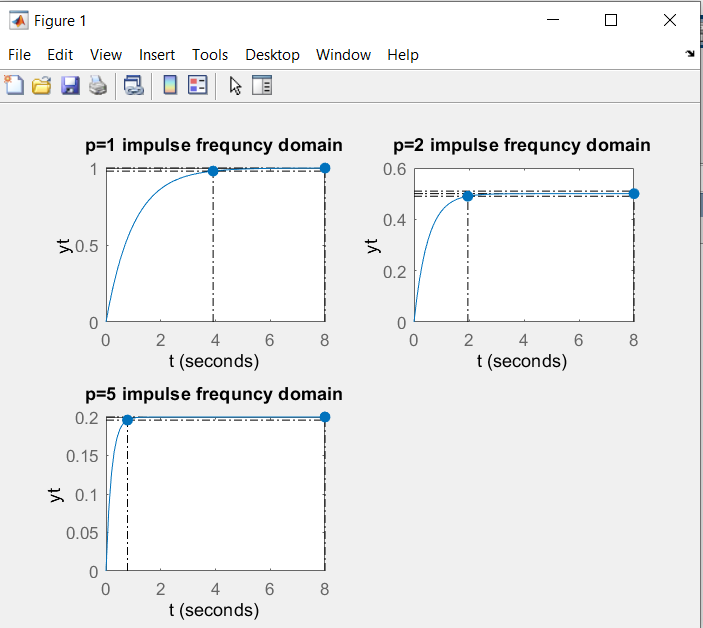

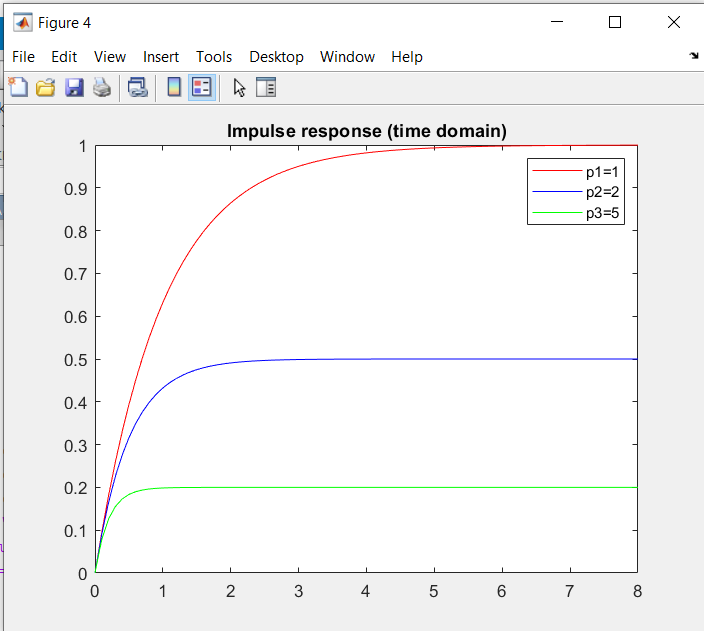

AS p INCRESES FRO  1 TO 5 THE SETLLING TIME DECREASES FORM 3.81 FOR P=1 TO 0.786 AT P=5

 
%with step as input in frequncy domain

Y_11=(R2+D)
Y11=series(Y_11,G1)
Y21=series(Y_11,G2)
Y31=series(Y_11,G3)

figure;
subplot(2,2,1);
step(Y11,t);
xlabel('t');
ylabel('yt');
title('p=1 step as imput frequncy domain');
%-------------------------
subplot(2,2,2);
step(Y21,t);
title('p=2 step as imput frequency domain');
xlabel('t');
ylabel('yt');
%-------------------------



% In time domain
num=1;
t=0:0.1:8;
p1 = 1;
p2 = 2;
p3 = 5;
den1=[1 p1 0];
den2=[1 p2 0];
den3=[1 p3 0];
y1_1=step(num,den1,t);
y2_2=step(num,den2,t);
y3_3=step(num,den3,t);
plot(t,y1_1,'r',t,y2_2,'b',t,y3_3,'g')
title('Step response time doamin')
legend('p1=1','p2=2','p3=5')
 

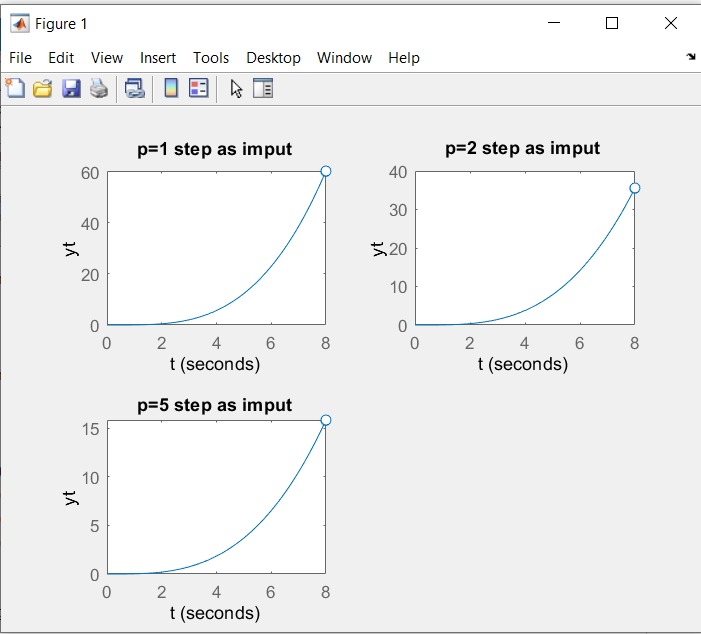

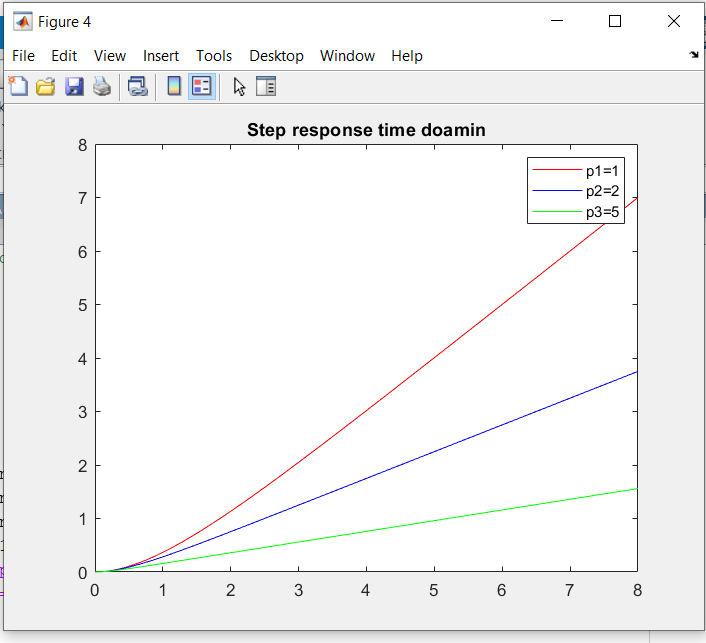

for all values of p the final value is infinity 

% step reference and a specified disturbance input in time domain

t=0:0.1:8;
p1 = 1;
p2 = 2;
p3 = 5;
g1=tf([0 0 1],[1 p1 0]);
g2=tf([0 0 1],[1 p2 0]);
g3=tf([0 0 1],[1 p3 0]);
a1=step(g1,t);
a2=step(g2,t);
a3=step(g3,t);
d = 0*t;
d(t>=0 & t<=4)=1;
d(t>4 & t<=8)=2;
y1= lsim(g1,d,t);
y2= lsim(g2,d,t);
y3= lsim(g3,d,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Step response with disturbance')
legend('p1=1','p2=2','p3=5')

% in frequecy domain 
s=tf('s');
d1num=(-2*exp(-8*s)+exp(-4*s)+-1)/s %taking laplace trnsform of dt

d1num =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   1
 
  C = 
       x1
   y1  -2
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 4  4 
 
Continuous-time state-space model.



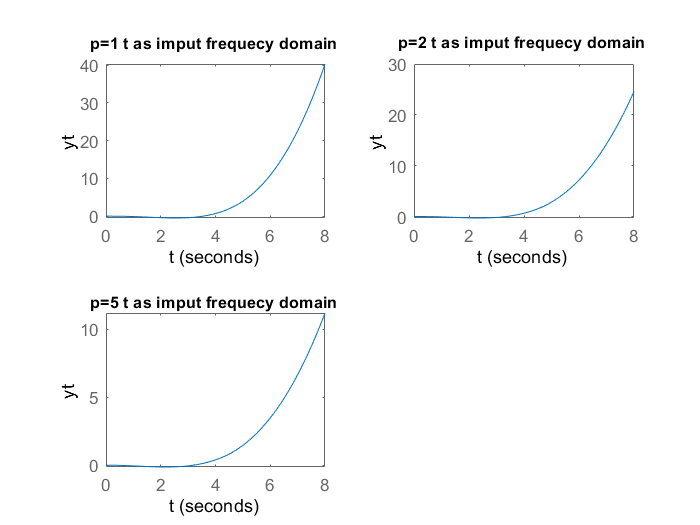

Y_111=(R2+d1num);
Y111=series(Y_111,G1);
Y211=series(Y_111,G2);
Y311=series(Y_111,G3);


figure;
subplot(2,2,1);
step(Y111,t);
xlabel('t');
ylabel('yt');
title('p=1 t as imput frequecy domain');
%-------------------------
subplot(2,2,2);
step(Y211,t);
title('p=2 t as imput frequecy domain');
xlabel('t');
ylabel('yt');
%-------------------------
subplot(2,2,3);
step(Y311,t);
title('p=5 t as imput frequecy domain');
xlabel('t');
ylabel('yt')

here also the final value streches to infinity as p increases

note we do notice a small dip in in the graphs due to the disturabance hwich takes it away from the normal step input behaviour